# synthetic_anticancer_pipeline_full_final.m

Full pipeline: feature exploration -> engineering -> baseline vs engineered models -> explainability (predictorImportance & permutation importance) -> dashboard Robust, safe, ready-to-run (CSV if present, otherwise synthetic)

clear; close all; clc;
rng(42);

## ---------------- User parameters ----------------

nSamplesDefault = 500;    % fallback sample count
nPhyto = 5; nOmics = 5; nNano = 5;  % synthetic structure if used
holdoutFraction = 0.30;   % train/test split
highCorrThresh = 0.95;    % de-correlation threshold
maxInteractions = 10;     % top pairwise interactions to keep
pcaExplainedThresh = 90;  % choose PCs to explain >= this (%) variance
minVarThreshold = 1e-8;   % low variance removal threshold
permRepeats = 5;          % repeats for permutation importance (averaging)

## ---------------- Load CSV if available ----------------

datasetLoaded = false;
fileList = { ...
 'synthetic_anticancer_dataset_for_pipeline.csv', ...
 'synthetic_anticancer_dataset_grouped_v2.csv', ...
 'synthetic_anticancer_dataset_grouped.csv', ...
 'synthetic_anticancer_dataset.csv', ...
 'synthetic_anticancer_dataset_1000_samples.csv' };

for f = 1:numel(fileList)
    if isfile(fileList{f})
        fprintf('Loading dataset: %s\n', fileList{f});
        T = readtable(fileList{f});
        datasetLoaded = true;
        break;
    end
end

## ---------------- Detect numeric features & targets robustly ----------------

X = []; featureNames = {}; yClass = []; yReg = [];
if datasetLoaded
    numericCols = varfun(@isnumeric, T, 'OutputFormat', 'uniform');
    Tnum = T(:, numericCols);
    % Heuristic: if >=3 numeric columns, treat last 2 as regression targets
    if width(Tnum) > 2
        Xtable = Tnum(:, 1:(end-2));
        yReg = table2array(Tnum(:, end-1:end));
    else
        Xtable = Tnum;
        yReg = [];
    end
    % Find binary column(s) (2 unique values) to use as classification target (heuristic: pick last)
    binCols = false(1,width(Tnum));
    for c = 1:width(Tnum)
        vals = Tnum{:,c};
        uniqVals = unique(vals(~isnan(vals)));
        if numel(uniqVals) == 2
            binCols(c) = true;
        end
    end
    if any(binCols)
        idx = find(binCols,1,'last');
        yClass = Tnum{:, idx};
        % remove from feature table if inside
        if idx <= width(Xtable)
            Xtable(:, idx) = [];
        end
    else
        yClass = [];
    end
    if ~isempty(Xtable)
        featureNames = Xtable.Properties.VariableNames;
        X = table2array(Xtable);
    else
        X = [];
    end
end

## ---------------- Synthetic fallback ----------------

if isempty(X)
    fprintf('No valid numeric features found or no CSV -> generating synthetic dataset (n=%d)...\n', nSamplesDefault);
    nSamples = nSamplesDefault;
    Phytochem = randn(nSamples,nPhyto);
    Omics = randn(nSamples,nOmics);
    Nano = randn(nSamples,nNano);
    X = [Phytochem Omics Nano];
    featureNames = [strcat("Phyto",string(1:nPhyto)), strcat("Omics",string(1:nOmics)), strcat("Nano",string(1:nNano))];
    sumPhyto = sum(Phytochem,2); sumOmics = sum(Omics,2); sumNano = sum(Nano,2);
    % classification target binary (-1,1)
    yClass = sumPhyto + 0.5*sumOmics + 0.3*sumNano + randn(nSamples,1);
    yClass = double(yClass>0); yClass(yClass==0) = -1;
    % regression targets
    yReg = [0.8*sumPhyto - 0.4*sumOmics + 0.6*sumNano + randn(nSamples,1), ...
            0.5*sumPhyto + 0.2*sumOmics + 0.4*sumNano + randn(nSamples,1)];
else
    nSamples = size(X,1);
end

No valid numeric features found or no CSV -> generating synthetic dataset (n=500)...


fprintf('Detected number of samples: %d\n', nSamples);

Detected number of samples: 500


## ---------------- Convert classification target to categorical (robust) ----------------

if ~isempty(yClass)
    yClass = categorical(string(yClass)); % convert -1/1 to '-1','1' then categorical
end

## ---------------- Train/test split ----------------

if nSamples <= 1
    warning('Too few samples: using full dataset for both train and test.');
    trainIdx = 1:nSamples; testIdx = 1:nSamples;
else
    cv = cvpartition(nSamples,'Holdout',holdoutFraction);
    trainIdx = training(cv); testIdx = test(cv);
end
Xtrain_raw = X(trainIdx, :);
Xtest_raw  = X(testIdx, :);
if ~isempty(yClass)
    yCtrain = yClass(trainIdx); yCtest = yClass(testIdx);
else
    yCtrain = []; yCtest = [];
end
if ~isempty(yReg)
    yRtrain = yReg(trainIdx, :); yRtest = yReg(testIdx, :);
else
    yRtrain = []; yRtest = [];
end

## ---------------- Stage-wise display ----------------

fprintf('--- Stage-wise Info ---\n');

--- Stage-wise Info ---


fprintf('Features: %d\n', size(X,2));

Features: 15


fprintf('Samples: %d  (Train=%d, Test=%d)\n', nSamples, sum(trainIdx), sum(testIdx));

Samples: 500  (Train=350, Test=150)


if ~isempty(yCtrain), fprintf('Classification target present\n'); end

Classification target present


if ~isempty(yRtrain), fprintf('Regression targets: %d\n', size(yRtrain,2)); end

Regression targets: 2


## ---------------- Feature exploration ----------------

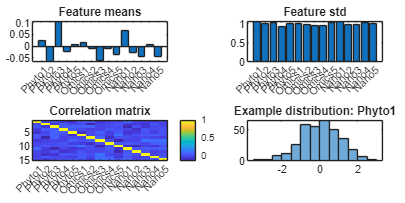

featMean = mean(Xtrain_raw,1);
featStd  = std(Xtrain_raw,0,1);
featVar  = var(Xtrain_raw,0,1);
corrMat = corr(Xtrain_raw,'Rows','pairwise');

figure('Name','Feature exploration','Position',[100 100 1200 600]);
tiledlayout(2,2,'Padding','compact','TileSpacing','compact');
nexttile; bar(featMean); title('Feature means'); xticks(1:numel(featureNames)); xticklabels(featureNames); xtickangle(45);
nexttile; bar(featStd); title('Feature std'); xticks(1:numel(featureNames)); xticklabels(featureNames); xtickangle(45);
nexttile; imagesc(corrMat); colorbar; title('Correlation matrix'); xticks(1:numel(featureNames)); xticklabels(featureNames); xtickangle(45);
nexttile; histogram(Xtrain_raw(:,1)); title(['Example distribution: ' featureNames{1}]);

## ---------------- Automatic de-correlation (drop highly collinear) ----------------

p = size(Xtrain_raw,2);
toRemoveCorr = false(1,p);
for a = 1:p
    for b = a+1:p
        if abs(corrMat(a,b)) > highCorrThresh
            % remove the one with higher mean absolute correlation
            if mean(abs(corrMat(a,:))) >= mean(abs(corrMat(b,:)))
                toRemoveCorr(a) = true;
            else
                toRemoveCorr(b) = true;
            end
        end
    end
end
keepIdx_corr = find(~toRemoveCorr);
fprintf('Dropped %d features due to high correlation (>|%.2f|).\n', sum(toRemoveCorr), highCorrThresh);

Dropped 0 features due to high correlation (>|0.95|).


## ---------------- Low-variance removal ----------------

featVar_train = featVar;
keepIdx_var = featVar_train > minVarThreshold;
fprintf('Dropped %d features due to low variance (threshold=%g).\n', sum(~keepIdx_var), minVarThreshold);

Dropped 0 features due to low variance (threshold=1e-08).


## ---------------- Combine keep indices ----------------

keepIdx = find(keepIdx_corr & keepIdx_var);
if isempty(keepIdx)
    warning('No features left after de-correlation/low-variance removal. Reverting to original features.');
    keepIdx = 1:p;
end
X_reduced_train = Xtrain_raw(:, keepIdx);
X_reduced = X(:, keepIdx); % full dataset reduced copy
reducedNames = featureNames(keepIdx);

## ---------------- Interaction terms (top by variance on training set) ----------------

pairs = nchoosek(1:numel(keepIdx),2);
interactions_full = [];
intNames = {};
if ~isempty(pairs)
    intVar = zeros(size(pairs,1),1);
    for k = 1:size(pairs,1)
        Itrain = Xtrain_raw(:, pairs(k,1)) .* Xtrain_raw(:, pairs(k,2));
        intVar(k) = var(Itrain);
    end
    [~,ord] = sort(intVar,'descend');
    nKeepPairs = min(maxInteractions, size(pairs,1));
    chosen = pairs(ord(1:nKeepPairs), :);
    interactions_full = zeros(nSamples, nKeepPairs);
    for k = 1:nKeepPairs
        interactions_full(:,k) = X(:, keepIdx(chosen(k,1))) .* X(:, keepIdx(chosen(k,2)));
        intNames{k} = sprintf('INT_%d_%d', keepIdx(chosen(k,1)), keepIdx(chosen(k,2)));
    end
else
    interactions_full = [];
    intNames = {};
end
fprintf('Generated %d interaction terms.\n', size(interactions_full,2));

Generated 10 interaction terms.


## ---------------- PCA (training-based) ----------------

Standardize reduced training features then PCA

mu_reduced = mean(X_reduced_train,1);
sigma_reduced = std(X_reduced_train,0,1) + eps;
X_reduced_train_z = (X_reduced_train - mu_reduced) ./ sigma_reduced;
X_reduced_full_z = (X_reduced - mu_reduced) ./ sigma_reduced; % full scaled for PCs

[coeff, score, latent, ~, explained] = pca(X_reduced_train_z);
cumExplained = cumsum(explained);
nPCs = find(cumExplained >= pcaExplainedThresh, 1, 'first');
if isempty(nPCs), nPCs = min(3, size(score,2)); end
PCs_full = (X_reduced_full_z * coeff(:,1:nPCs));
fprintf('Using %d PCs to explain >= %d%% variance.\n', nPCs, pcaExplainedThresh);

Using 13 PCs to explain >= 90% variance.


## ---------------- Build engineered matrix (train/test standardized) ----------------

Standardize reduced features using training mu/sigma (apply to full)

X_reduced_z_full = X_reduced_full_z;  % already standardized
% Standardize interactions using training subset of interactions
if ~isempty(interactions_full)
    inter_train = interactions_full(trainIdx, :);
    mu_int = mean(inter_train, 1);
    sigma_int = std(inter_train, 0, 1) + eps;
    interactions_z_full = (interactions_full - mu_int) ./ sigma_int;
else
    interactions_z_full = [];
end

% Engineered features = [reduced_z, interactions_z, PCs]
engineered_full = [X_reduced_z_full, interactions_z_full, PCs_full];
engineeredNames = [reducedNames, intNames, strcat("PC", string(1:nPCs))];

% Split engineered into train/test
Xtrain_eng = engineered_full(trainIdx, :);
Xtest_eng  = engineered_full(testIdx, :);

% Baseline features: standardize raw features with training stats
mu_raw = mean(Xtrain_raw,1);
sigma_raw = std(Xtrain_raw,0,1) + eps;
Xtrain_raw_z = (Xtrain_raw - mu_raw) ./ sigma_raw;
Xtest_raw_z  = (Xtest_raw  - mu_raw) ./ sigma_raw;

% If engineered empty, fallback to raw
if isempty(Xtrain_eng) || isempty(Xtest_eng)
    Xtrain_eng = Xtrain_raw_z;
    Xtest_eng = Xtest_raw_z;
    engineeredNames = featureNames;
    warning('Engineered features empty -> falling back to raw standardized features.');
end

## ---------------- Model lists ----------------

classModelList = {
    'Decision Tree', @(X,Y) fitctree(X,Y)
    'k-NN', @(X,Y) fitcknn(X,Y,'NumNeighbors',5)
    'SVM', @(X,Y) fitcsvm(X,Y,'KernelFunction','rbf','Standardize',true)
    'Random Forest', @(X,Y) fitcensemble(X,Y,'Method','Bag')
    'Logistic', @(X,Y) fitclinear(X,Y,'Learner','logistic')
    };

regModelList = {
    'Linear Regression', @(X,Y) fitlm(X,Y)
    'SVM Regression', @(X,Y) fitrsvm(X,Y,'KernelFunction','rbf','Standardize',true)
    'Random Forest', @(X,Y) fitrensemble(X,Y,'Method','Bag')
    'GLM Regression', @(X,Y) fitglm(X,Y)
    };

nClassModels = size(classModelList,1);
nRegModels = size(regModelList,1);

## ---------------- Baseline vs Engineered: Classification ----------------

Running classification models (baseline vs engineered)...


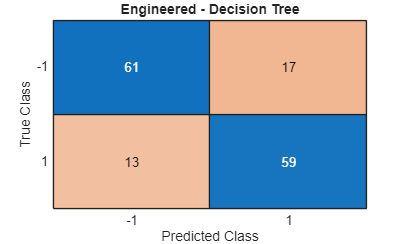

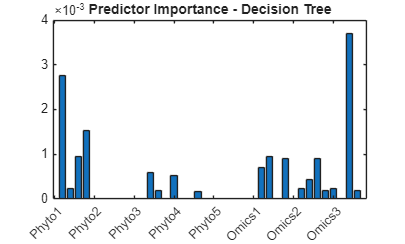

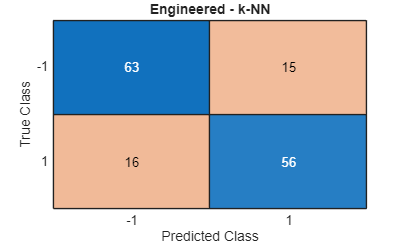

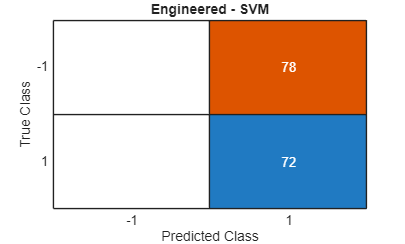

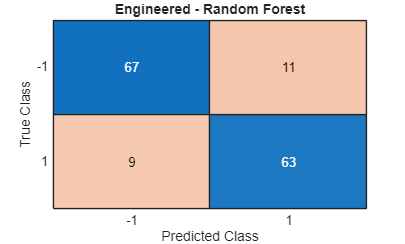

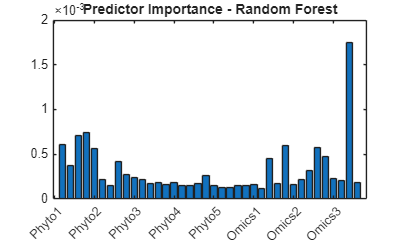

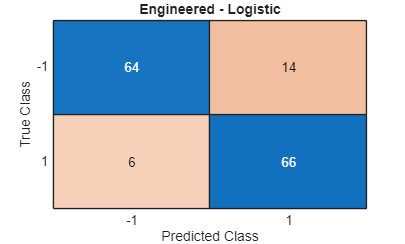

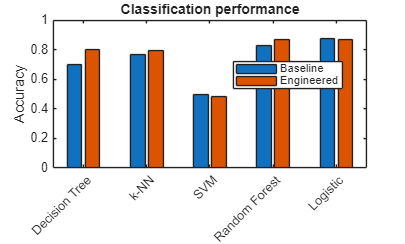

baselineClassAcc = nan(1,nClassModels);
engineeredClassAcc = nan(1,nClassModels);

if ~isempty(yCtrain)
    if numel(unique(yCtrain)) < 2
        warning('Training split has fewer than 2 classes; skipping classification models.');
    else
        fprintf('Running classification models (baseline vs engineered)...\n');
        for i = 1:nClassModels
            % baseline on raw standardized
            try
                mdl_base = classModelList{i,2}(Xtrain_raw_z, yCtrain);
                ypred_base = predict(mdl_base, Xtest_raw_z);
                baselineClassAcc(i) = mean(ypred_base == yCtest);
            catch ME
                warning('Baseline classification model %s failed: %s', classModelList{i,1}, ME.message);
                baselineClassAcc(i) = NaN;
            end
            % engineered
            try
                mdl_eng = classModelList{i,2}(Xtrain_eng, yCtrain);
                ypred_eng = predict(mdl_eng, Xtest_eng);
                engineeredClassAcc(i) = mean(ypred_eng == yCtest);
                % show confusion for engineered
                figure('Name',['Confusion (Engineered) - ' classModelList{i,1}]); confusionchart(yCtest, ypred_eng); title(['Engineered - ' classModelList{i,1}]);
                % predictorImportance if available, else fallback later to permutation
                try
                    imp = predictorImportance(mdl_eng);
                    figure('Name',['Predictor Importance - ' classModelList{i,1}]); bar(imp); xticklabels(engineeredNames); xtickangle(45);
                    title(['Predictor Importance - ' classModelList{i,1}]);
                catch
                    % not all models support predictorImportance
                end
            catch ME
                warning('Engineered classification model %s failed: %s', classModelList{i,1}, ME.message);
                engineeredClassAcc(i) = NaN;
            end
        end
        % summary plot
        figure('Name','Classification: baseline vs engineered'); 
        bar([baselineClassAcc; engineeredClassAcc]'); set(gca,'XTickLabel', classModelList(:,1)); xtickangle(45);
        legend({'Baseline','Engineered'},'Location','best'); ylabel('Accuracy'); title('Classification performance');
    end
end

## ---------------- Baseline vs Engineered: Regression ----------------

Running regression models (baseline vs engineered)...


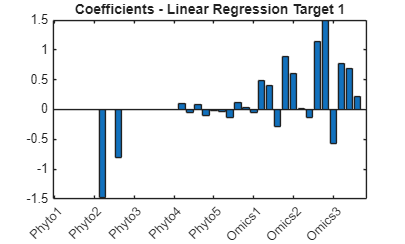

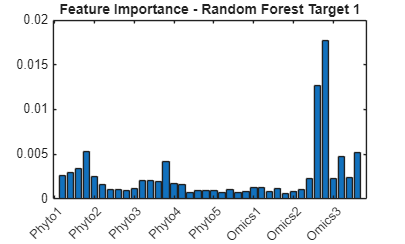

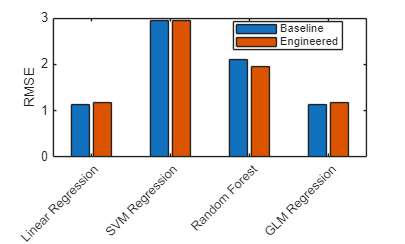

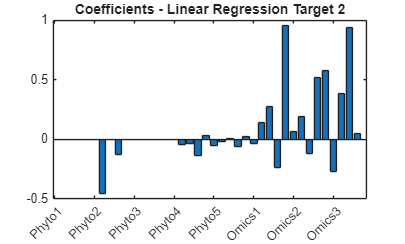

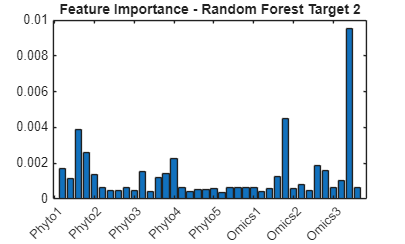

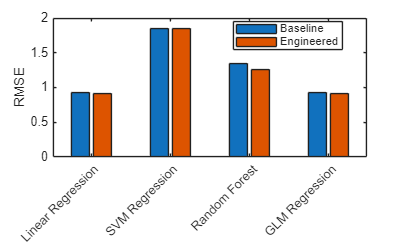

nTargets = size(yRtrain,2);
baselineRegRMSE = nan(nTargets, nRegModels);
engineeredRegRMSE = nan(nTargets, nRegModels);

if ~isempty(yRtrain)
    fprintf('Running regression models (baseline vs engineered)...\n');
    for t = 1:nTargets
        for i = 1:nRegModels
            try
                mdl_base = regModelList{i,2}(Xtrain_raw_z, yRtrain(:,t));
                ypred_base = predict(mdl_base, Xtest_raw_z);
                baselineRegRMSE(t,i) = sqrt(mean((yRtest(:,t) - ypred_base).^2));
            catch ME
                warning('Baseline reg model %s target %d failed: %s', regModelList{i,1}, t, ME.message);
                baselineRegRMSE(t,i) = NaN;
            end
            try
                mdl_eng = regModelList{i,2}(Xtrain_eng, yRtrain(:,t));
                ypred_eng = predict(mdl_eng, Xtest_eng);
                engineeredRegRMSE(t,i) = sqrt(mean((yRtest(:,t) - ypred_eng).^2));
                % explainability
                try
                    if isa(mdl_eng,'LinearModel')
                        coeffs = mdl_eng.Coefficients.Estimate(2:end);
                        figure('Name',['Reg Coeffs - ' regModelList{i,1} ' T' num2str(t)]); bar(coeffs); xticklabels(engineeredNames); xtickangle(45);
                        title(['Coefficients - ' regModelList{i,1} ' Target ' num2str(t)]);
                    else
                        imp = predictorImportance(mdl_eng); %#ok<NASGU>
                        figure('Name',['Reg Importance - ' regModelList{i,1} ' T' num2str(t)]); 
                        bar(imp); xticklabels(engineeredNames); xtickangle(45); title(['Feature Importance - ' regModelList{i,1} ' Target ' num2str(t)]);
                    end
                catch
                    % ignore explain errors
                end
            catch ME
                warning('Engineered reg model %s target %d failed: %s', regModelList{i,1}, t, ME.message);
                engineeredRegRMSE(t,i) = NaN;
            end
        end
        % plot comparison for this target
        figure('Name',['Regression RMSE comparison - Target ' num2str(t)]);
        bar([baselineRegRMSE(t,:); engineeredRegRMSE(t,:)]');
        set(gca,'XTickLabel', regModelList(:,1)); xtickangle(45); legend({'Baseline','Engineered'},'Location','best'); ylabel('RMSE');
    end
end

## ---------------- Permutation (SHAP-like) importance ----------------

Classification: pick best engineered classification model (max acc)

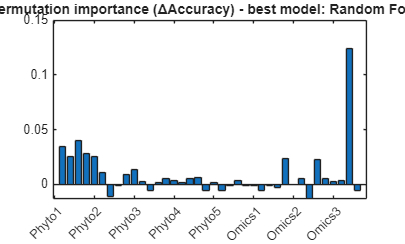

if ~isempty(yCtrain) && any(~isnan(engineeredClassAcc))
    [~,bestIdxC] = max(engineeredClassAcc);
    bestModelNameC = classModelList{bestIdxC,1};
    try
        bestMdlC = classModelList{bestIdxC,2}(Xtrain_eng, yCtrain);
        baseAcc = mean(predict(bestMdlC, Xtest_eng) == yCtest);
        permImpC = zeros(1, size(Xtrain_eng,2));
        % repeated random shuffles averaged
        for j = 1:size(Xtrain_eng,2)
            deltaAccs = zeros(permRepeats,1);
            for r = 1:permRepeats
                Xperm = Xtest_eng;
                Xperm(:,j) = Xperm(randperm(size(Xperm,1)), j);
                permAcc = mean(predict(bestMdlC, Xperm) == yCtest);
                deltaAccs(r) = baseAcc - permAcc;
            end
            permImpC(j) = mean(deltaAccs);
        end
        figure('Name','Permutation importance (Classification)'); bar(permImpC); xticklabels(engineeredNames); xtickangle(45);
        title(sprintf('Permutation importance (ΔAccuracy) - best model: %s', bestModelNameC));
    catch ME
        warning('Permutation importance for classification failed: %s', ME.message);
    end
end

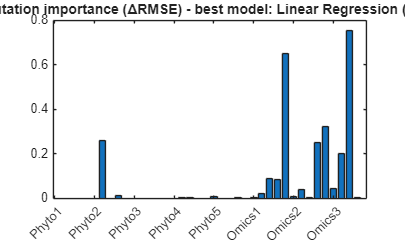


% Regression: pick best engineered regression model (min mean RMSE)
if ~isempty(yRtrain) && any(~isnan(engineeredRegRMSE(:)))
    avgRMSE = nanmean(engineeredRegRMSE,1);
    [~,bestIdxR] = min(avgRMSE);
    bestModelNameR = regModelList{bestIdxR,1};
    % choose target with best performance for that model
    [~,bestTargetForModel] = min(engineeredRegRMSE(:,bestIdxR));
    try
        bestMdlR = regModelList{bestIdxR,2}(Xtrain_eng, yRtrain(:,bestTargetForModel));
        yRef = yRtest(:, bestTargetForModel);
        basePred = predict(bestMdlR, Xtest_eng);
        baseRMSE = sqrt(mean((yRef - basePred).^2));
        permImpR = zeros(1, size(Xtrain_eng,2));
        for j = 1:size(Xtrain_eng,2)
            deltaRMSEs = zeros(permRepeats,1);
            for r = 1:permRepeats
                Xperm = Xtest_eng;
                Xperm(:,j) = Xperm(randperm(size(Xperm,1)), j);
                yperm = predict(bestMdlR, Xperm);
                permRMSE = sqrt(mean((yRef - yperm).^2));
                deltaRMSEs(r) = permRMSE - baseRMSE;
            end
            permImpR(j) = mean(deltaRMSEs);
        end
        figure('Name','Permutation importance (Regression)'); bar(permImpR); xticklabels(engineeredNames); xtickangle(45);
        title(sprintf('Permutation importance (ΔRMSE) - best model: %s (target %d)', bestModelNameR, bestTargetForModel));
    catch ME
        warning('Permutation importance for regression failed: %s', ME.message);
    end
end

## ---------------- Final combined dashboard ----------------

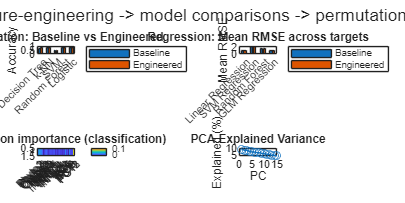

figure('Name','Final ML Performance Summary','Position',[200 200 1200 600]);
tiledlayout(2,2,'TileSpacing','compact','Padding','compact');
% classification summary
nexttile;
if exist('baselineClassAcc','var') && any(~isnan(baselineClassAcc))
    bar([baselineClassAcc; engineeredClassAcc]'); set(gca,'XTickLabel', classModelList(:,1)); xtickangle(45);
    legend({'Baseline','Engineered'},'Location','bestoutside'); ylabel('Accuracy'); title('Classification: Baseline vs Engineered');
else
    text(0.2,0.5,'No classification results','FontSize',12);
end
% regression summary (mean RMSE across targets)
nexttile;
if exist('baselineRegRMSE','var') && ~all(isnan(baselineRegRMSE(:)))
    baselineMean = nanmean(baselineRegRMSE,1); engMean = nanmean(engineeredRegRMSE,1);
    bar([baselineMean; engMean]'); set(gca,'XTickLabel', regModelList(:,1)); xtickangle(45);
    legend({'Baseline','Engineered'},'Location','bestoutside'); ylabel('Mean RMSE'); title('Regression: Mean RMSE across targets');
else
    text(0.2,0.5,'No regression results','FontSize',12);
end
% feature importance heatmap (if permImpR or permImpC exist)
nexttile;
if exist('permImpC','var') && ~isempty(permImpC)
    imagesc(permImpC); colorbar; title('Permutation importance (classification)'); xticks(1:numel(engineeredNames)); xticklabels(engineeredNames); xtickangle(45);
elseif exist('permImpR','var') && ~isempty(permImpR)
    imagesc(permImpR); colorbar; title('Permutation importance (regression)'); xticks(1:numel(engineeredNames)); xticklabels(engineeredNames); xtickangle(45);
else
    text(0.2,0.5,'No permutation importance computed','FontSize',12);
end
% PCA explained
nexttile;
if exist('explained','var')
    plot(explained,'-o'); xlabel('PC'); ylabel('Explained (%)'); title('PCA Explained Variance'); grid on;
else
    text(0.2,0.5,'No PCA computed','FontSize',12);
end

sgtitle('Pipeline summary: feature-engineering -> model comparisons -> permutation importance');


fprintf('Pipeline finished. Review figures for stage-wise outputs and importance.\n');

Pipeline finished. Review figures for stage-wise outputs and importance.
